## **Kobylański Przemysław, 297253**

## **Metodu numeryczne - projekt 3**

3.1. Napisać własne funkcje obliczające całki z wykorzystaniem kwadratur Newtona-Cotesa:

a) funkcję `MojProstokat(fun,a,b,npanel)` - do obliczania całki metodą prostokątów, gdzie `fun` jest całkowaną funkcją (podana w oddzielnym      m-file'u), `a` i `b` to początek i koniec przedziału całkowania, `npanel` to liczba podprzedziałów na którą dzielimy przedział `[a,b]`.

b) funkcję `MojTrapez(fun,a,b,npanel)` - do obliczania całki metodą trapezów, gdzie `fun` jest całkowaną funkcją (podana w oddzielnym           m-file'u), `a` i `b` to początek i koniec przedziału całkowania, `npanel` to liczba podprzedziałów na którą dzielimy przedział `[a,b]`.

c) funkcję `MojaParabola(fun,a,b,npanel)` - do obliczania całki metodą parabol, gdzie `fun` jest całkowaną funkcją (podana w oddzielnym m-file'u), `a` i `b` to początek i koniec przedziału całkowania, `npanel` to liczba podprzedziałów na którą dzielimy przedział `[a,b]`.

d) funkcję `MojeTrzyOsme(fun,a,b,npanel) `- do obliczania całki metodą 3/8 Newtona, gdzie `fun `jest całkowaną funkcją (podana w oddzielnym      m-file'u), `a `i `b `to początek i koniec przedziału całkowania, `npanel `to liczba podprzedziałów na którą dzielimy przedział `[a,b]`.

clear all;
%początek i koniec przedziału
a = 1;
b = 5;


%Obliczanie wyników i wyświetlanie
integral=MojProstokat(fun, a, b, 5);
disp("Całka obliczona metodą prostokątów: "+integral);

Całka obliczona metodą prostokątów: 53.12


integral=MojTrapez(fun, a, b, 5);
disp("Całka obliczona metodą trapezów: "+integral);

Całka obliczona metodą trapezów: 53.76


integral=MojaParabola(fun, a, b, 4);
disp("Całka obliczona metodą parabol: "+integral);

Całka obliczona metodą parabol: 53.3333


integral=MojeTrzyOsme(fun, a, b, 6);
disp("Całka obliczona metodą 3/8 Newtona: "+integral);

Całka obliczona metodą 3/8 Newtona: 53.3333


3.2. Obliczyć wartość całki

I =∫ xe^−x dx

metodą prostokątów, trapezów i parabol dla liczby węzłów wynoszącej kolejno 2, 4, 8, 16, 32. Dla każdej liczby węzłów obliczyć długość przedziałów h. Dodatkowo podać błąd każdej metody w zależności od liczby węzłów (sporządzić wspólny wykres): E(f ) = |I − ∫ f (x)dx|.

Dokładną wartość całki I policzyć za pomocą Symbolic Math Toolbox. Zbadać zależność błędu wyniku od stopnia złożoności kwadratury.

clear all;
%zdefiniowanie całkowanej funkcji
syms x;
fun=@(x) x.*exp(-x);
%granice całkowania
a=0;
b=5;
%wartość dokładna
integralAcc = double(int(fun,x, a, b));
disp("Całka dokładna: "+integralAcc);

Całka dokładna: 0.95957




% Liczby węzłów
n = [2, 4, 8, 16, 32];
integrals = zeros(3, length(n));
errors = zeros(3, length(n));

for i = 1:length(n)
    % Wyniki metod
    integralProst = MojProstokat(fun, a, b, n(i));
    integralTrap = MojTrapez(fun, a, b, n(i));
    integralPar = MojaParabola(fun, a, b, n(i));
    
    % Błędy metod
    errorProst = abs(integralAcc -integralProst);
    errorTrap = abs(integralAcc - integralTrap);
    errorPar = abs(integralAcc - integralPar);
    
    % Zapisywanie wartości
    integrals(:, i) = [integralProst;integralTrap; integralPar];
    errors(:, i) = [errorProst; errorTrap; errorPar];
    
    % Wyświetlamy wartości całki dla każdej metody i każdej liczby węzłów
    disp(['Liczba węzłów: ' num2str(n(i))]);
    disp(['Całka (metoda prostokątów): ' num2str(integralProst)]);
    disp(['Błąd (metoda prostokątów): ' num2str(errorProst)]);
    disp(['Całka (metoda trapezów): ' num2str(integralTrap)]);
    disp(['Błąd (metoda trapezów): ' num2str(errorTrap)]);
    disp(['Całka (metoda parabol): ' num2str(integralPar)]);
    disp(['Błąd (metoda parabol): ' num2str(errorPar)]);
    disp('-----------------------------');
end

Liczba węzłów: 2


Całka (metoda prostokątów): 1.1158


Błąd (metoda prostokątów): 0.15623


Całka (metoda trapezów): 0.55514


Błąd (metoda trapezów): 0.40443


Całka (metoda parabol): 0.71212


Błąd (metoda parabol): 0.24746


-----------------------------


Liczba węzłów: 4


Całka (metoda prostokątów): 1.0181


Błąd (metoda prostokątów): 0.058496


Całka (metoda trapezów): 0.83547


Błąd (metoda trapezów): 0.1241


Całka (metoda parabol): 0.92892


Błąd (metoda parabol): 0.030654


-----------------------------


Liczba węzłów: 8


Całka (metoda prostokątów): 0.97574


Błąd (metoda prostokątów): 0.016165


Całka (metoda trapezów): 0.92677


Błąd (metoda trapezów): 0.032801


Całka (metoda parabol): 0.9572


Błąd (metoda parabol): 0.0023682


-----------------------------


Liczba węzłów: 16


Całka (metoda prostokątów): 0.96372


Błąd (metoda prostokątów): 0.0041439


Całka (metoda trapezów): 0.95125


Błąd (metoda trapezów): 0.0083176


Całka (metoda parabol): 0.95942


Błąd (metoda parabol): 0.00015662


-----------------------------


Liczba węzłów: 32


Całka (metoda prostokątów): 0.96061


Błąd (metoda prostokątów): 0.0010425


Całka (metoda trapezów): 0.95749


Błąd (metoda trapezów): 0.0020868


Całka (metoda parabol): 0.95956


Błąd (metoda parabol): 9.9308e-06


-----------------------------


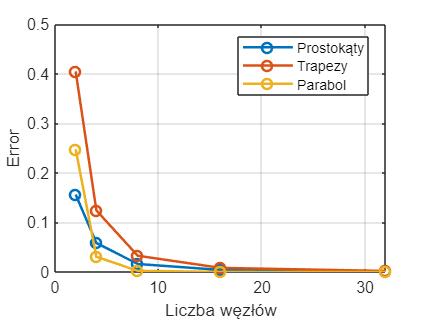

% Wykres zmiany błędu
figure;
plot(n, errors(1, :), 'o-', 'LineWidth', 1.5, 'DisplayName', 'Prostokąty');
hold on;
plot(n, errors(2, :), 'o-', 'LineWidth', 1.5, 'DisplayName', 'Trapezy');
plot(n, errors(3, :), 'o-', 'LineWidth', 1.5, 'DisplayName', 'Parabol');
xlabel('Liczba węzłów');
ylabel('Error');
legend('Location', 'best');
grid on;

3.3.Zastosować metodę `3/8` Newtona do obliczenia wartości całki

Q = 2/√π∫e^−x`2 `dx

dla liczby węzłów wynoszącej kolejno 3, 6, 9, 12. Dla każdej liczby węzłów obliczyć długość przedziałów h. Dodatkowo podać błąd metody w zależności od liczby węzłów (sporządzićwykres): E(f ) = |Q − ∫ f (x)dx|. Dokładną wartość całki Q policzyć za pomocą Symbolic Math Toolbox.

clear all;
% Definicja funkcji
syms x;
fun=@(x) (2./(sqrt(pi))).*exp(-(x.^2));

% Przedział całkowania
a = 0;
b = 1;

% Liczby węzłów (wielokrotności 3)
n = [3, 6, 9, 12];


% Inicjalizacja wektorów % Obliczanie wartości dokładnej całki Q
Q = int(fun, x, a, b);
disp("Dokładna wartość całki: " + double(Q));

Dokładna wartość całki: 0.8427


h = zeros(1, length(n));
errors = zeros(1, length(n));

% Iteracyjne obliczenia dla różnych n
for i = 1:length(n)
    % Obliczenie funkcja MojeTrzyOsme.m
    integral = MojeTrzyOsme(fun, a, b, n(i));
    
    % Szerokość podprzedziałów
    h(i) = (b - a) / n(i);
    
    % Błąd
    error = abs(Q - integral);
    errors(i) = double(error);
    
    % Wyświetlanie wyników
   % Wyświetlanie wartości całki i błędu
    disp(['Liczba węzłów: ' num2str(n(i))]);
    disp(['Wartość całki: ' sprintf('%.6f', double(integral))]);
    disp(['Błąd: ' sprintf('%.6f', double(error)) newline]);
end

Liczba węzłów: 3


Wartość całki: 0.842891


Błąd: 0.000190



Liczba węzłów: 6


Wartość całki: 0.842717


Błąd: 0.000016



Liczba węzłów: 9


Wartość całki: 0.842704


Błąd: 0.000003



Liczba węzłów: 12


Wartość całki: 0.842702


Błąd: 0.000001



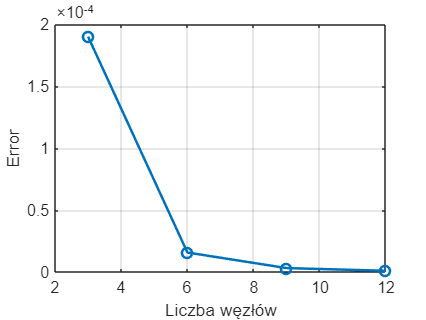


% Wykres zmiany błędu
figure;
plot(n, errors, 'o-', 'LineWidth', 1.5);
xlabel('Liczba węzłów');
ylabel('Error');
grid on;

3.4. Wyznacz całkę

U = ∫x`2/(`√(1 + x)(1 − x))dx

za pomocą kwadratury Gaussa-Czebyszewa dla 61 węzłów. Porównaj otrzymany wynik z wynikiem otrzymanym za pomocą Symbolic Math Toolbox. Przyjąć arytmetykę `double`.

clear all;
syms x;
% Zdefiniowanie funkcji
fun = @(x) (x.^2)/(sqrt((1+x)*(1-x)));

a = -1;
b = 1;
n = 61; % liczba węzłów

% Wartość dokładna
integralAcc = double(int(fun, x, a, b));
fprintf('Dokładna wartość całki: %.8f\n', integralAcc);

Dokładna wartość całki: 1.57079633



%dostosowanie funkcji do metody węzłów czebyszewa
f = @(x) x.^2./sqrt(1-x.^2) .* sqrt(1-(x.^2));

%wyznaczenie wagi
weight = pi/(n + 1);
i = [0:1:n];
x = cos((2*i+1)*pi/(2*n+2));
% obliczenie wartości całki metodą Czebyszewa
integralCzeb = sum(weight * f(x));

fprintf('Wartość całki obliczona metodą Czebyszewa: %.8f\n', integralCzeb);

Wartość całki obliczona metodą Czebyszewa: 1.57079633


3.5. Stosując kwadraturę Gaussa-Hermite'a dla pięciu węzłów zbadaj zbieżność całki

V =∫ x^`2*`e^(−x^`2) `dx.

Porównaj otrzymany wynik z wynikiem otrzymanym za pomocą Symbolic Math Toolbox. Przyjąć arytmetykę `double`.

clear all;
syms x;
% Zdefiniowanie funkcji
fun = @(x) x.^2 .* exp(-x.^2);

n = 5; % liczba węzłów

% Wartość dokładna
integralAcc = double(int(fun, x, -inf, inf));
fprintf('Dokładna wartość całki: %.8f\n', integralAcc);

Dokładna wartość całki: 0.88622693


3.6. Napisać `m-plik` realizujący numeryczne obliczanie pochodnej funkcji

y = 2 + 2 sin^`2`(x) + cos^`2`(x).

Obliczenia wykonać w zakresie [0, 5]. Przyjąć stały krok różniczkowania h = 0.01. Porównać przebieg pochodnej y wyznaczonej numerycznie z przebiegiem pochodnej y wyznaczonej analitycznie (Symbolic Math Toolbox ).

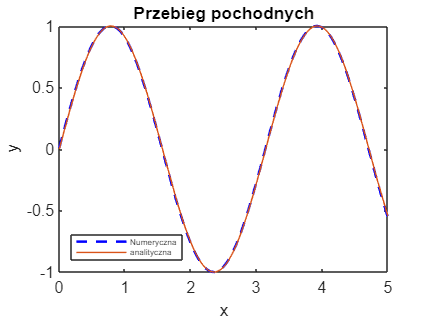

clear all;
% krok różniczkowania w zakresie 0-5
step = 0.01;
h=0:step:5;
% Definicja funkcji
syms x;
y = @(x) 2 + 2*sin(x).^2 + cos(x).^2;

%obliczenie pochodnych numerycznie i analitycznie
numerical = (y(h+step) - y(h)) / step;
analytical=diff(y,x);

%wizualizacja wyników
figure
plot(h, numerical, '--b','LineWidth', 1.5)
hold on
fplot(x, analytical, [0,5])
title('Przebieg pochodnych')
xlabel('x')
ylabel('y')
legend('Numeryczna', 'analityczna',Location='southwest',FontSize= 5)

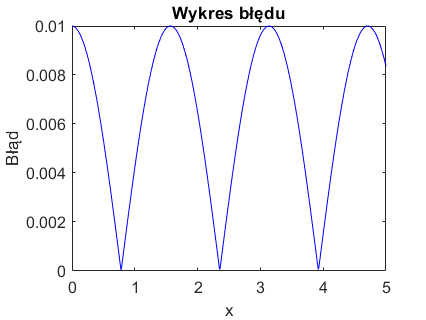


% Podstawienie wartości h w wyrażeniach symbolicznych
analytical_vals = subs(analytical, x, h);

% Różnica między pochodnymi
error = abs(analytical_vals - numerical);

% Wykres błędu
figure
plot(h, error, '-b')
title('Wykres błędu')
xlabel('x')
ylabel('Błąd')

3.7. Wyniki pomiarów prędkości (w metrach na sekundę) pewnego urządzenia wyścigowego podane są w tablicy: vy=[0 1 2 3 4 5 6 7 8 9 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 9 8 7 6 5 4 3 2 1 0]. Określić przyspieszenie tego urządzenia. Wiadomo, że pomiary były dokonywane co 10 sekund.

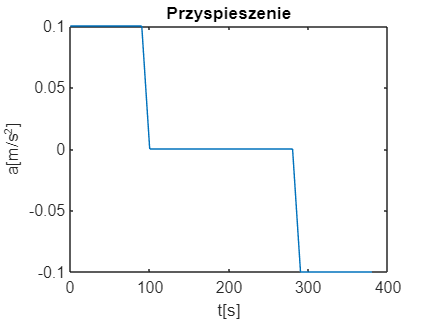

clear all;
v=[0 1 2 3 4 5 6 7 8 9 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 9 8 7 6 5 4 3 2 1 0];
%krok między pomiarami
step = 10;
%czasy pomiarów
t = 0 : step: (length(v)-2)*step;
accel = 0; 

%obliczanie przyspieszenia
for( i = 1 : length(v)-1)
    accel(i) = (v(i+1) - v(i)) / step;
end
% Wykres
figure
plot(t, accel);
title("Przyspieszenie");
xlabel("t[s]");
ylabel("a[m/s^2]");

3.8. Przyjmijmy, że pewna funkcja y = f (x), dana jest w postaci dyskretnej, jako ciąg wartości zmiennej niezależnej x i odpowiadaj¡cych im wartości y. Chcemy znaleźć wartości pochodnej tej funkcji, które nazwiemy d. Napisać najprostszą funkcję różniczkującą `function d = MojaPierwszaPochodna(x,y)` na podstawie ilorazu różnicowego. Porównać na jednym wykresie pochodną analityczną i numeryczną. Przyjąć h = 10^−`1`, 10^−`2`, 10^−`3`. W zależności od h obliczyć błąd przybliżenia dla x = 1. Zastanowić się, czy mogą być takie przypadki, w których funkcja `MojaPierwszaPochodna` nie będzie działać prawidłowo. W zadaniu przyjąć funkcję f (x) = 2 sin(3x^`2`) na przedziale [0, 2π]

clear all;

% Dane wejściowe
syms x;
fun = @(x) 2.*sin(3.*(x.^2));
a = 0;
b = 2*pi();

% Obliczenie pochodnej analitycznej
analytical = diff(fun, x);
fprintf("Pochodna policzona analitycznie: %s\n", char(analytical));

Pochodna policzona analitycznie: 12*x*cos(3*x^2)


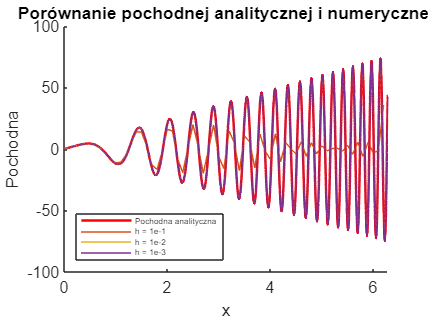


% Obliczenie pochodnej numerycznej
h = [1e-1, 1e-2, 1e-3];
x1 = a:h(1):b;
x2 = a:h(2):b;
x3 = a:h(3):b;

numerical1 = MojaPierwszaPochodna(x1, fun(x1));
numerical2 = MojaPierwszaPochodna(x2, fun(x2));
numerical3 = MojaPierwszaPochodna(x3, fun(x3));


% Obliczenie błędów
error1 = norm(double(subs(analytical, x, x1)) - numerical1);
error2 = norm(double(subs(analytical, x, x2)) - numerical2);
error3 = norm(double(subs(analytical, x, x3)) - numerical3);

% Wykres
figure
hold on
fplot(analytical, [0, 2*pi], 'r', 'LineWidth', 1.5)
plot(x1, numerical1)
plot(x2, numerical2)
plot(x3, numerical3)

title('Porównanie pochodnej analitycznej i numerycznej')
xlabel('x')
ylabel('Pochodna')
legend('Pochodna analityczna', 'h = 1e-1', 'h = 1e-2', 'h = 1e-3', 'Location', 'southwest', 'FontSize', 5)


% Wyświetlenie błędów
fprintf('Błąd dla h = 1e-1: %.8f\n', error1);

Błąd dla h = 1e-1: 248.18673053


fprintf('Błąd dla h = 1e-2: %.8f\n', error2);

Błąd dla h = 1e-2: 17.65811414


fprintf('Błąd dla h = 1e-3: %.8f\n', error3);

Błąd dla h = 1e-3: 1.23012588
